# Simulacion discreta 

## Examen TIPO A : En la sabana africana 

En la sabana africana se producen continuamente enfrentamientos entre diferentes  especies por los escasos recursos disponibles. El principal recurso es el agua.

 Al agua van todas las especies a beber, pero hay dos que viven en ella y que no se llevan bien: los cocodrilos y los hipopótamos. Aunque habitualmente se respetan, porque ambos  saben las posibilidades del otro, en algunas ocasiones se producen enfrentamientos por la  posesión de una determinada parcela del río por diversos motivos que no vienen al caso. 

Queremos modelar un sistema que simule el enfrentamiento entre cocodrilos e  hipopótamos. Cada especie se caracteriza por una fortaleza diferente. Así, los hipopótamos  son más torpes en sus movimientos de ataque, pero su poderosa mandíbula hace que sean  muy temibles en su defensa. Los cocodrilos, por el contrario, son muy rápidos en el ataque, pero mucho más vulnerables cuando se defienden. 

En estos combates entre las dos especies, la variación en el número de hipopótamos que  se enfrentan con los cocodrilos vendrá determinada por el número de los primeros,  afectados de un factor que determina su capacidad defensiva menos el número de los  segundos afectados por su capacidad ofensiva. De la misma manera se comporta la  variación en el número de cocodrilos: vendrá determinada por el número de estos  afectados por su capacidad defensiva menos el número de hipopótamos con su capacidad  ofensiva. 

Suponemos que se enfrentan ocho hipopótamos contra diez cocodrilos. 

Se pide:

### **a) Modelar el sistema propuesto **


$$\begin{array}{l}
H:\textrm{número}\;\textrm{de}\;\textrm{hipopótamos}\\
C:\textrm{número}\;\textrm{de}\;\textrm{cocodrilos}\\
\textrm{Dh}:\textrm{capacidad}\;\textrm{defensiva}\;\textrm{de}\;\textrm{los}\;\textrm{hipopótamos}\;\\
\textrm{Oh}:\textrm{capacidad}\;\textrm{ofensiva}\;\textrm{de}\;\textrm{los}\;\textrm{hipopótamos}\;\\
\textrm{Dc}:\textrm{capcidad}\;\textrm{defensiva}\;\textrm{de}\;\textrm{los}\;\textrm{cocodrilos}\;\\
\textrm{Oc}:\textrm{capacidad}\;\textrm{ofensiva}\;\textrm{de}\;\textrm{los}\;\textrm{cocodrilos}\;
\end{array}$$
 


$$\left\lbrace \begin{array}{ll}
\Delta H=H_{n+1} -H_n =\textrm{Dh}*H_n -\textrm{Oc}*C_n  & \\
\Delta C=C_{n+1} -C_n =\textrm{DC}*C_n -\textrm{OH}*H_n  & 
\end{array}\right.$$



$$\left\lbrack \begin{array}{c}
H_{n+1} \\
C_{n+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1+\textrm{Dh} & -\textrm{Oc}\\
-\textrm{Oh} & 1+\textrm{Dc}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
H_n \\
C_n 
\end{array}\right\rbrack$$


Sabemos que: 


$$\begin{array}{l}
\textrm{Dh}>\textrm{Dc}\\
\textrm{Oc}>\textrm{Oh}
\end{array}$$


### **b) Estudiar analíticamente su estabilidad **

Para estudiar si el sistema es estable realizaremos dos pruebas. La primera determinara el punto de estabilizacion del sistema general para cualquier numero de hipopotamos y cocodrilos iniciales. La segunda determinara si existen unos parametros iniciales los cuales estabilicen el sistema dado con 8

hipopotamos y 10 cocodrilos.

clc,clear, clf 
syms H C Dh Oc Oh Dc % variables simbolicas a usar

Creamos las primeras ecuaciones para la primera prueba

sistema = [H == (1+Dh)*H - Oc*C, C == -Oh*H + (1+Dc)*C];
solucion = solve(sistema,[H,C])

solucion = struct with fields:
    H: 0
    C: 0


El resultado obtenido es que en general el sistema se estabiliza con el numero de hipopotamos 0 y cocodrilos 0. 

Ahora realizaremos la segunda prueba, particular de nuestro problema.

H0 = 8; 
C0 = 10; 

sistema = [H0 == (1+Dh)*H0 - Oc*C0, C0 == -Oh*H0 + (1+Dc)*C0];
sol = solve(sistema,[Dh,Oh])

sol = struct with fields:
    Dh: (5*Oc)/4
    Oh: (5*Dc)/4


Vemos una estabilidad en el sistema con 8 hipopótamos y 10 cocodrilos cuando:

$\textrm{Dh}=\frac{5*\textrm{Oc}}{4}$ , $\textrm{Oh}=\frac{5*\textrm{Dc}}{4\;}$

### **c) Determinar cuál es capacidad ofensiva y defensiva de ambas especies para que no  haya ni vencedores ni vencidos.**

Con el resultado obtenido en el apartado anterior, podemos determinar el caso en que no haya vencedores ni vencidos debido a la no variacion de las poblaciones. Para ello tomaremos los parametros que se obtuvieron  como resultado. 

Dh = (5*Oc)/4;
Oh = (5*Dc)/ 4 ;
parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];
tiempo = 25; 
[nH,nC] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado: 

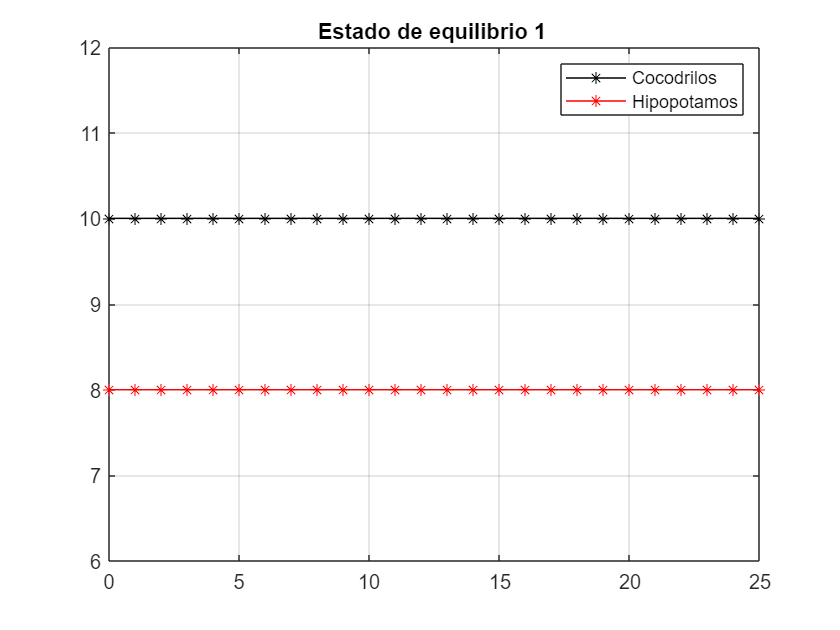

plot(0:25, nC,'-*k')
hold on
plot(0:25, nH,'-*r')
grid on
axis([0 25 6 12])
legend('Cocodrilos','Hipopotamos')
title('Estado de equilibrio 1 ')
hold off

Vamos a anilzar el resultado con el otro punto de equilibrio encontrado en el apartado anterior. 

Oh = 0;
Dh = 0; 
Oc = 0; 
Dc = 0; 
parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];

[nH,nC] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado: 

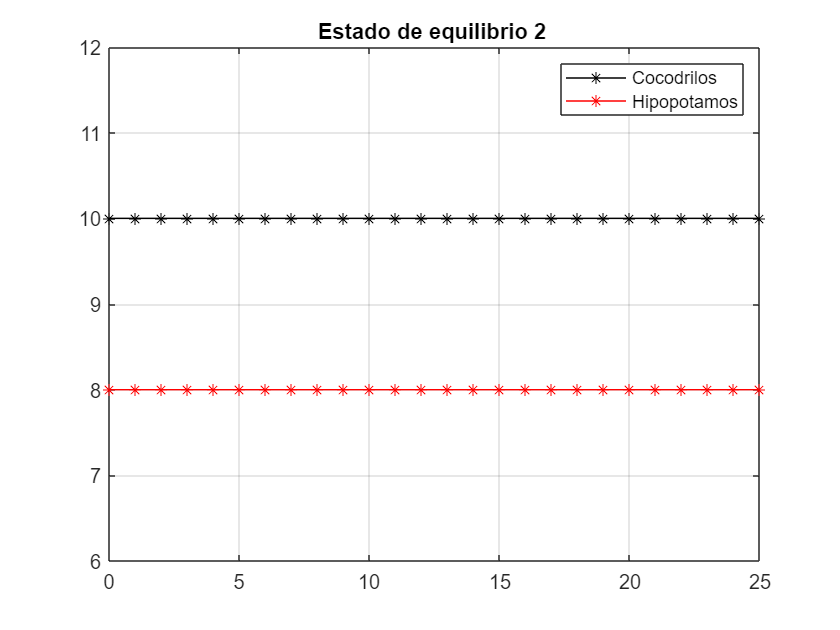

plot(0:25, nC,'-*k')
hold on
plot(0:25, nH,'-*r')
grid on
axis([0 25 6 12])
legend('Cocodrilos','Hipopotamos')
title('Estado de equilibrio 2 ')
hold off

### **d) Si los enfrentamientos terminaran cuando alguna de las dos especies se  desapareciera ¿Quién resultaría vencedor? **

**Justificar detalladamente todas las respuestas y añadir los gráficos que sean necesarios  para fundamentar las respuestas y el funcionamiento del modelo.**

Para ver si alguna de las dos especies desaparece debemos, jugar con las diferentes variables del sistema. Para ello, analiaremos diferente soluciones en función de los valores de las variables: 

#### **Caso 1: Dh < 5 * Oc / 4 y Oh < 5*Dc / 4  **

Oc = 0.2;
Dc = 0.2;
Oh = (5 * Oc) / 4 - 0.01;
Dh = (5 * Dc) / 4 - 0.01; 

parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];
tiempo = 100;
[nH,nC, i] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado:

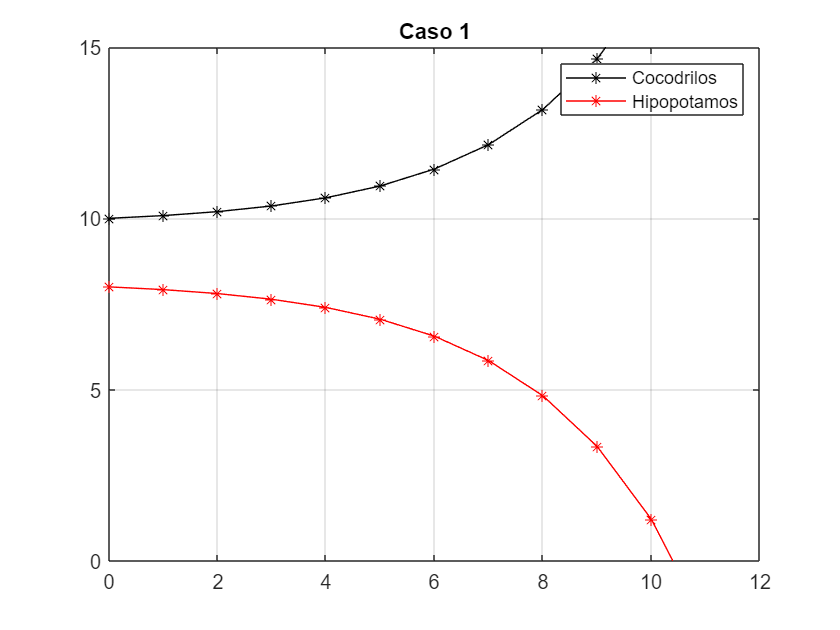

plot(0:i-1, nC,'-*k')
hold on
plot(0:i-1, nH,'-*r')
grid on
axis([0 i 0 15])
legend('Cocodrilos','Hipopotamos')
title('Caso 1')
hold off


resultado (1, nC, nH, i)

CASO 1: Vencen los Cocodrilos en el tiempo: 11

#### **Caso 2: Dh > 5 * Oc / 4 y Oh > 5*Dc / 4  **

Oc = 0.2;
Dc = 0.2;
Oh = (5 * Oc) / 4 + 0.01;
Dh = (5 * Dc) / 4 + 0.01; 

parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];
[nH,nC,i] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado:

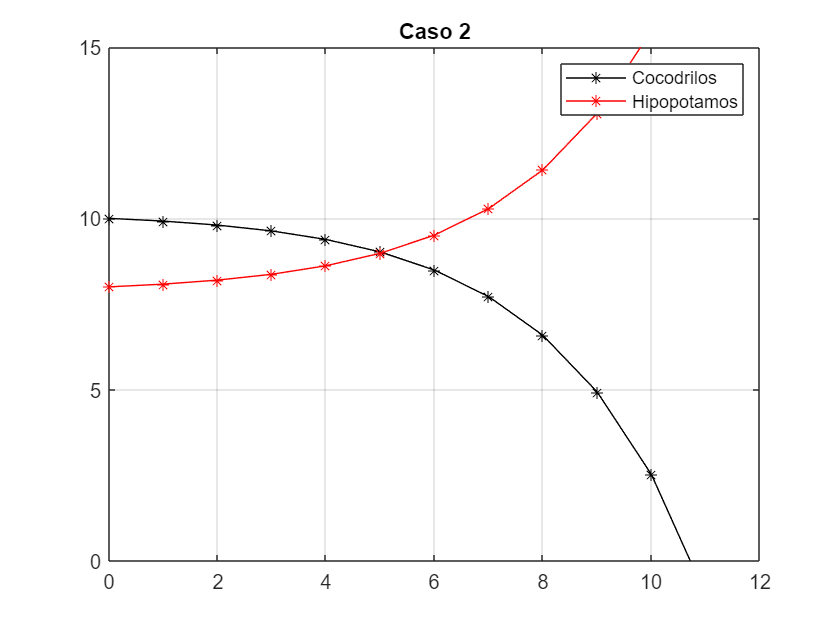

plot(0:i-1, nC,'-*k')
hold on
plot(0:i-1, nH,'-*r')
grid on
axis([0 i 0 15])
legend('Cocodrilos','Hipopotamos')
title('Caso 2')
hold off


resultado (2, nC, nH, i)

CASO 2: Vencen los Hipopótamos en el tiempo: 11

#### **Caso 3: Dh < 5 * Oc / 4 y Oh > 5*Dc / 4  **

Oc = 0.2;
Dc = 0.2;
Oh = (5 * Oc) / 4 + 0.01;
Dh = (5 * Dc) / 4 - 0.01; 

parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];
[nH,nC,i] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado:

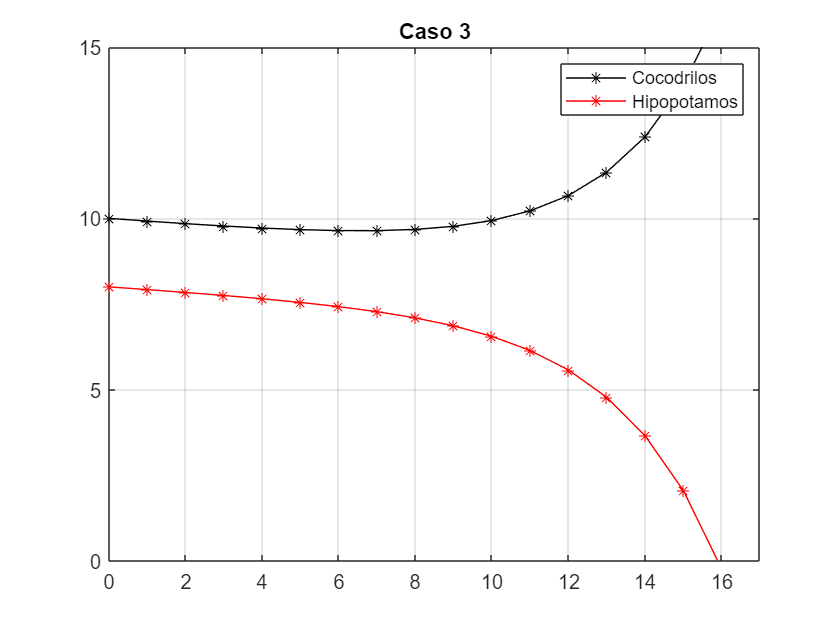

plot(0:i-1, nC,'-*k')
hold on
plot(0:i-1, nH,'-*r')
grid on
axis([0 i 0 15])
legend('Cocodrilos','Hipopotamos')
title('Caso 3')
hold off


resultado (3, nC, nH, i)

CASO 3: Vencen los Cocodrilos en el tiempo: 16

#### **Caso 4: Dh > 5 * Oc / 4 y Oh < 5*Dc / 4  **

Oc = 0.2;
Dc = 0.2;
Oh = (5 * Oc) / 4 - 0.01;
Dh = (5 * Dc) / 4 + 0.01; 

parametros = [1 + Dh, -Oc; -Oh, 1+ Dc];
[nH,nC,i] = enfrentamiento(0, H0, C0, parametros, tiempo);

Observamos gráficamente el resultado:

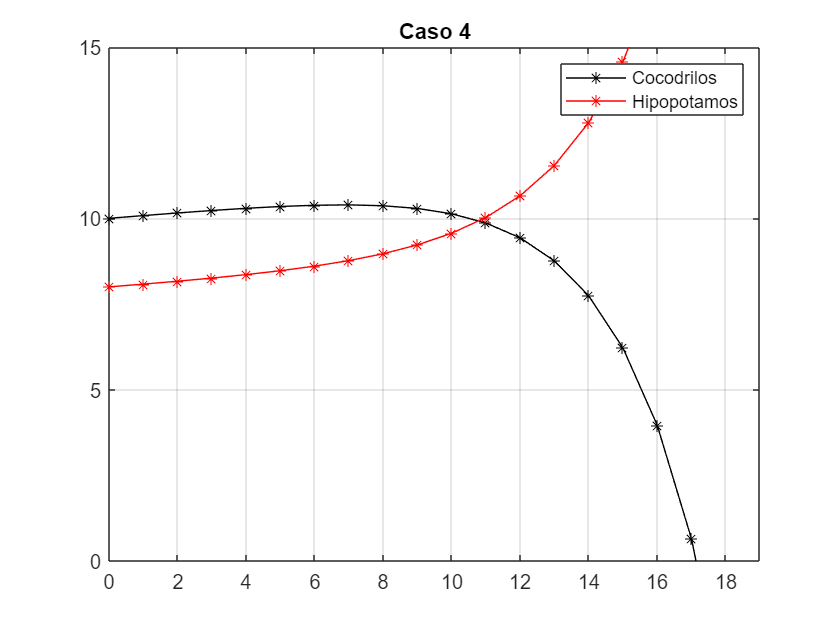

plot(0:i-1, nC,'-*k')
hold on
plot(0:i-1, nH,'-*r')
grid on
axis([0 i 0 15])
legend('Cocodrilos','Hipopotamos')
title('Caso 4')
hold off


resultado (4, nC, nH, i)

CASO 4: Vencen los Hipopótamos en el tiempo: 18

function [H, C, i] = enfrentamiento(reloj, H0, C0, param, fin)

i = 1;
H(i) = H0;
C(i) = C0;
% rutina de parada 
while(reloj<fin)
    i = i + 1; 

    % Rutina de evento
    r = param*[H(reloj+1);C(reloj+1)];
    H(i) =  r(1);
    C(i) =  r(2);
    
    % Rutina de parada ( animales negativos ) 
    if r(1) <= 0 || r(2) <= 0
        break;
    end  
    reloj = reloj + 1;
end

end

Función para mostrar los resultados de los diferentes casos 

function [] = resultado (caso, nC, nH, i)
    if nC > nH 
        fprintf('CASO %d: Vencen los Cocodrilos en el tiempo: %d',caso ,i - 1);
    else  
        fprintf('CASO %d: Vencen los Hipopótamos en el tiempo: %d',caso ,i - 1);
    end
end